f = @(x) (atan(x) - 1);
fp = @(x) (1 / (1 + x.^2));
x0 = 2;
tol = 1e-8;
N = 100;
[c, n, err] = Newtons_method(f, fp, x0, tol, N)

c = 1.5574

n = 3

err = 6.9016e-06

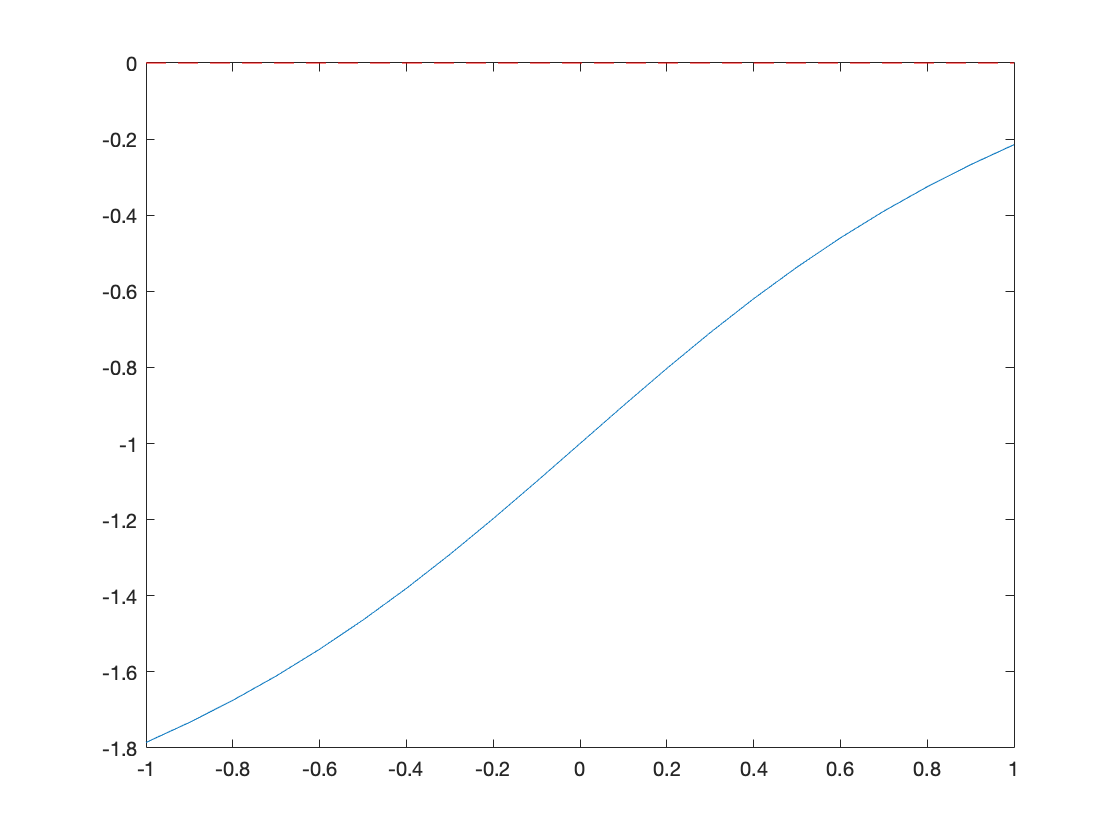

x = 0:length(c)-1;
plot([-1:0.1:1],f([-1:0.1:1]),[-1:0.1:1],0*[-1:0.1:1], 'r--')

function[c, n, err] = Newtons_method(f, fp, x0, tol, N)

n = 0;
c = x0 - (f(x0) / fp(x0));
err = abs(c - x0);
while abs(err > tol) && (n < N)
    c = x0 - (f(x0) / fp(x0));
    err = abs(c - x0);
    
    if abs(err < 1e-3)
        break;
    end
    
    n = n + 1;
    x0 = c;
    x(n + 1) = x0;
end
end